folderPath ="C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Videos\"

folderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Videos\"

txtFileName = [ "Tip Thrust-Experiment-2024-10-07_17-54-35 Mass B", "Tip Thrust Experiment-2024-10-07_17-57-43 Mass A", "Tip Thrust-Experiment-2024-10-15_19-52-21 Mass A- Rotational Velocity"]

txtFileName = 1×3 string array
    "Tip Thrust-Experiment-2024-10-07_17-54-35 Mass B"    "Tip Thrust Experiment-2024-10-07_17-57-43 Mass A"    "Tip Thrust-Experiment-2024-10-15_19-52-21 Mass A- Rotational Velocity"


csvFileName = [ "Tip Thrust-Experiment-2024-10-07_17-54-35", "Tip Thrust-Experiment-2024-10-07_17-57-43","Speed Test"]

csvFileName = 1×3 string array
    "Tip Thrust-Experiment-2024-10-07_17-54-35"    "Tip Thrust-Experiment-2024-10-07_17-57-43"    "Speed Test"


imageFolderPath ="C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\"

imageFolderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\"

figureWidth = 700; % Width in pixels
figureHeight = 500; % Height in pixels

set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

file =1

file = 1


txtFilePath = fullfile(folderPath,txtFileName(file) + ".txt") 

txtFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Videos\Tip Thrust-Experiment-2024-10-07_17-54-35 Mass B.txt"

pitchVideoResults= readtable(txtFilePath)

pitchVideoResults = 666×2 table
    Var1     Var2 
    _____    _____

        0     -6.4
    0.033       -8
    0.067    -40.2
      0.1    -44.7
    0.133    -50.1
    0.167    -46.6
      0.2    -48.8
    0.233    -47.8
    0.267    -45.4
      0.3    -44.6
    0.333    -42.3
    0.367    -40.6
      0.4    -41.1
    0.433      -42
    0.467    -40.2
      0.5    -41.8


pitchVideoResults.Properties.VariableNames = {'Time', 'Pitch'};

csvFilePath = fullfile(folderPath,csvFileName(file) + ".csv") 

csvFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Videos\Tip Thrust-Experiment-2024-10-07_17-54-35.csv"

pitchSensorResults= readtable(csvFilePath,"VariableNamingRule","preserve")

pitchSensorResults = 228×5 table
    Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2
    ____________    _____________    ____________    _______________    _______________

         50              200              0                 0                 -1       
         50              200              0                 0                 -2       
         50              200              0                 0                 -1       
         50              200              0                 0                 -2       
         50              200              0                 0                 -2       
         50              200              0                 0                 -1       
         50              200              0                 0                 -2       
    


originalIndices = linspace(1, 165-103+1, length(103:165));

interpolatedData = interp1(originalIndices, pitchSensorResults.("Current Pitch 2")(103:165), linspace(1, length(103:165), length(pitchVideoResults.Time)), 'linear');
interpolatedTargetPitch = interp1(originalIndices, pitchSensorResults.("Target Pitch")(103:165), linspace(1, length(103:165), length(pitchVideoResults.Time)), 'linear');


plot(pitchVideoResults.Time, -pitchVideoResults.Pitch,'color',"#009DC4","DisplayName","Tracker Pitch")
hold on
plot(pitchVideoResults.Time*0.76-0.7,interpolatedData,'color',"#D81B60","DisplayName", "Sensor Pitch")
% plot(pitchVideoResults.Time*0.875-0.8,interpolatedTargetPitch)
hold off
legend;
xlabel("Time [s]")
ylabel("Pitch [°]")
title("Actual Pitch vs Detected Pitch")
xlim([0,18])

set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
imageFilePath = fullfile(imageFolderPath,"Pitch Graph-" + csvFileName(file) + ".png")

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\Pitch Graph-Tip Thrust-Experiment-2024-10-07_17-54-35.png"

dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
close(gcf);

file =2

file = 2


txtFilePath = fullfile(folderPath,txtFileName(file) + ".txt") 

txtFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Videos\Tip Thrust Experiment-2024-10-07_17-57-43 Mass A.txt"

pitchVideoResults= readtable(txtFilePath)

pitchVideoResults = 630×2 table
    Var1     Var2 
    _____    _____

    0.033    -11.5
    0.067    -12.5
      0.1    -12.5
    0.133    -12.4
    0.167    -12.4
      0.2      -14
    0.233    -17.6
    0.267    -21.4
      0.3      -25
    0.333    -30.4
    0.367    -35.5
      0.4    -39.4
    0.433    -44.2
    0.467    -45.1
      0.5    -45.9
    0.533    -45.5


pitchVideoResults.Properties.VariableNames = {'Time', 'Pitch'};

csvFilePath = fullfile(folderPath,csvFileName(file) + ".csv") 

csvFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Videos\Tip Thrust-Experiment-2024-10-07_17-57-43.csv"

pitchSensorResults= readtable(csvFilePath,"VariableNamingRule","preserve");

originalIndices = linspace(1, 165-103+1, length(132:202));

interpolatedData = interp1(originalIndices, pitchSensorResults.("Current Pitch 2")(132:202), linspace(1, length(132:202), length(pitchVideoResults.Time)), 'linear');
interpolatedTargetPitch = interp1(originalIndices, pitchSensorResults.("Target Pitch")(132:202), linspace(1, length(132:202), length(pitchVideoResults.Time)), 'linear');


plot(pitchVideoResults.Time, -pitchVideoResults.Pitch,'color',"#009DC4","DisplayName","Tracker Pitch")
hold on
plot((pitchVideoResults.Time-1.8),interpolatedData,'color',"#D81B60","DisplayName", "Sensor Pitch")
hold off
legend;
xlabel("Time [s]")
ylabel("Pitch [°]")
title("Actual Pitch vs Detected Pitch")
xlim([0,16])
set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
imageFilePath = fullfile(imageFolderPath,"Pitch Graph-" + csvFileName(file) + ".png")

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\Pitch Graph-Tip Thrust-Experiment-2024-10-07_17-57-43.png"

dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
close(gcf);

file =3;

txtFilePath = fullfile(folderPath,txtFileName(file) + ".txt") ;
pitchVideoResults= readtable(txtFilePath);
pitchVideoResults.Properties.VariableNames = {'Time', 'Speed'};

csvFilePath = fullfile(folderPath,csvFileName(file) + ".csv") ;
pitchSensorResults= readtable(csvFilePath,"VariableNamingRule","preserve");

originalIndices = linspace(1, 165-103+1, length(103:165));

fs=0.033

fs = 0.0330

cutOffFrequency = 0.0015;
    nOrder = 8;
    cutOffFrequency/(fs/2)

ans = 0.0909



    [b,a] = butter(nOrder,cutOffFrequency/(fs/2));
    speedFiltered = filtfilt(b,a,-pitchVideoResults.Speed(2:end-1)/6);

plot((1:length(pitchVideoResults.Time)-2)*3.4*9.8e-3, speedFiltered,'color',"#009DC4","DisplayName","Tracker Angular Velocity")
hold on
plot((1:length(pitchSensorResults.("Current Speed")(4900:8269)))*9.8e-3, pitchSensorResults.("Current Speed")(4900:8269),'color',"#D81B60","DisplayName", "Sensor Angular Velocity")
legend;
xlabel("Time [s]")
ylabel("Angular Velocity [rpm]")
title("Actual Angular Veloicty vs Detected Angular Veloicty")
hold off
set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
imageFilePath = fullfile(imageFolderPath,"Pitch Graph-" + csvFileName(file) + ".png")

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\Pitch Graph-Speed Test.png"

dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
close(gcf);


    folderPath = ["C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep Singular\"]

folderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep Singular\"

    fileName = ["TEST 120.3"]

fileName = "TEST 120.3"

    imageName = ["Pitch Sweep"]

imageName = "Pitch Sweep"

    imageFolderPath ="C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\"

imageFolderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\"

    figureWidth = 900; % Width in pixels
    figureHeight = 500; % Height in pixels
    file = 1

file = 1

        filePath = fullfile(folderPath(file),fileName(file) + ".csv") 

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep Singular\TEST 120.3.csv"


    resultsBackwardsDirection= readtable(filePath,"VariableNamingRule","preserve")

resultsBackwardsDirection = 7334×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-16 18:44:37        120             18.26             0                -10                11               -19            -19             4             -19    
    2024-10-16 18:44:37        120             18.26             0                -10                11 


    figure;
    plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, resultsBackwardsDirection.("Current Pitch 1"),'linewidth',1,'DisplayName','Rotor 1 Pitch','color',"#009DC4")
    hold on
    plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, resultsBackwardsDirection.("Target Pitch"),'r','linewidth',1,'DisplayName','Rotor 1 Target Pitch', 'color',"#f5b227")
    plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, resultsBackwardsDirection.("Current Pitch 2"),'linewidth',1,'DisplayName','Rotor 2 Pitch','color',"#D81B60")
    % plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, aveargaePitch,'linewidth',1,'DisplayName','Average Pitch')
    ylim([-20,60])
    xlim([500,length(resultsBackwardsDirection.("Current Pitch 1"))*2.5/4].*10e-3)
    hold off
    ylabel('Pitch [°]');
    xlabel('Time [s]');
    title("PID Repsone for Pitch Change");
    legend;

    set(gcf, 'Position', [100, 100, 1500, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Pitch Graph-" + imageName(file) + ".png")

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\Pitch Graph-Pitch Sweep.png"

    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);

folderPath = ["C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\" , "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\","C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Speed Sweep\","C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep Singular"]

folderPath = 1×4 string array
    "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\"    "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\"    "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Speed Sweep\"    "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep Singular"


fileName = ["TEST 60.1","TEST 60.1", "TEST 2"]

fileName = 1×3 string array
    "TEST 60.1"    "TEST 60.1"    "TEST 2"


imageName = ["Reverse Flight", "Forward Flight", "Speed Sweep"]

imageName = 1×3 string array
    "Reverse Flight"    "Forward Flight"    "Speed Sweep"


imageFolderPath ="C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\"

imageFolderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\"

figureWidth = 900; % Width in pixels
figureHeight = 500; % Height in pixels

% Set the figure size
set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

for file = 1:length(fileName)
    filePath = fullfile(folderPath(file),fileName(file) + ".csv") 
    resultsBackwardsDirection= readtable(filePath,"VariableNamingRule","preserve")
    previousSpeed = 40;
    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

    aveargaePitch = zeros(1,length(resultsBackwardsDirection.("Current Pitch 1")));
    for i = 1:length(resultsBackwardsDirection.("Current Pitch 1"))
        aveargaePitch(i) = (resultsBackwardsDirection.("Current Pitch 1")(i) + resultsBackwardsDirection.("Current Pitch 2")(i))/2;
    end


## Pitch

    figure;
    plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, resultsBackwardsDirection.("Current Pitch 1"),'linewidth',1,'DisplayName','Rotor 1 Pitch','color',"#009DC4")
    hold on
    plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, resultsBackwardsDirection.("Target Pitch"),'r','linewidth',1,'DisplayName','Rotor 1 Target Pitch', 'color',"#f5b227")
    plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, resultsBackwardsDirection.("Current Pitch 2"),'linewidth',1,'DisplayName','Rotor 2 Pitch','color',"#D81B60")
    % plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, aveargaePitch,'linewidth',1,'DisplayName','Average Pitch')
    ylim([-25,90])
    xlim([400,length(resultsBackwardsDirection.("Current Pitch 1"))*2.5/4].*10e-3)
    hold off
    ylabel('Pitch [°]');
    xlabel('Time [s]');
    title(fullfile("Pitch Variation for " + imageName(file) + " Mode"));
    legend;

    set(gcf, 'Position', [100, 100, 1500, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Pitch Graph-" + imageName(file) + ".png")
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);

## Loadcells

    resultsBackwardsDirection.("Load Cell 1") = -(resultsBackwardsDirection.("Load Cell 1") - resultsBackwardsDirection.("Load Cell 1")(1)).*0.0098;
    loadcell1 = rmmissing(resultsBackwardsDirection.("Load Cell 1"));
    loadcell1(isoutlier(resultsBackwardsDirection.("Load Cell 1"), 'mean')) = NaN;
    loadcell1 = fillmissing(loadcell1, 'linear');

    resultsBackwardsDirection.("Load Cell 2")  = -(resultsBackwardsDirection.("Load Cell 2")  - resultsBackwardsDirection.("Load Cell 2") (1)).*0.0098;
    loadcell2 = rmmissing(resultsBackwardsDirection.("Load Cell 2") );
    % loadcell2(isoutlier(resultsFrequencySweep.("Load Cell 2") , 'mean')) = NaN;
    loadcell2 = fillmissing(loadcell2, 'linear');

    resultsBackwardsDirection.("Load Cell 3")  = -((resultsBackwardsDirection.("Load Cell 3") ) - (resultsBackwardsDirection.("Load Cell 3") (1))).*0.0098.*0.9;
    loadcell3 = rmmissing(resultsBackwardsDirection.("Load Cell 3") );
    % loadcell3(isoutlier(resultsFrequencySweep.("Load Cell 3") , 'mean')) = NaN;
    loadcell3 = fillmissing(loadcell3, 'linear');

    resultsBackwardsDirection.("Load Cell 4")  = -((resultsBackwardsDirection.("Load Cell 4") ) - (resultsBackwardsDirection.("Load Cell 4") (1))).*0.0098.*0.8;
    loadcell4 = rmmissing(resultsBackwardsDirection.("Load Cell 4") );
    loadcell4 = fillmissing(loadcell4, 'linear');

    aveargaeLoadcells = zeros(1,length(loadcell1));
    for i = 1:length(loadcell1)
        aveargaeLoadcells(i) = (loadcell1(i) + loadcell1(i) + loadcell1(i) + loadcell1(i));
    end
    figure;
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell1)),loadcell1,'DisplayName','Load Cell 1')
    hold on
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell2)),loadcell2,'DisplayName','Load Cell 2')
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell3)),loadcell3,'DisplayName','Load Cell 3')
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell4)),loadcell4,'DisplayName','Load Cell 4')
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(aveargaeLoadcells)),aveargaeLoadcells,'r','linewidth',1, 'DisplayName','Combined Load Cells')
    xlim([0,length(resultsBackwardsDirection.Timestamp)*10e-3])
    hold off
    ylabel('Thrust [N]');
    xlabel('Time [s]');
    title(fullfile("Unfiltered Loadcell Output for " + imageName(file) + " Mode"));
    legend;
    TotalLoadcellScalled = interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcells)), aveargaeLoadcells, 1:length(aveargaePitch), 'linear')
    linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell2))
    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

    imageFilePath = fullfile(imageFolderPath,"Unfiltered Loadcell Readings-" +  imageName(file)+ ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell1)),loadcell1)
    period = 0.44;
    fs = 1/period;   % Sampling Frequency
    nyquist_freq = fs/2 ;
    previousItterationPoint = 1


## FFT

    cutOffFrequency = 0.2;
    nOrder = 4;

    [b,a] = butter(nOrder,cutOffFrequency/(fs/2));
    loadcell1Filtered = filtfilt(b,a,loadcell1);
    loadcell2Filtered = filtfilt(b,a,loadcell2);
    loadcell3Filtered = filtfilt(b,a,loadcell3);
    loadcell4Filtered = filtfilt(b,a,loadcell4);

    aveargaeLoadcellsFiltered = zeros(1,length(loadcell1Filtered));
    deltaThrust = (loadcell4Filtered+loadcell1Filtered) - (loadcell3Filtered+loadcell2Filtered);

    for i = 1:length(loadcell1Filtered)
        aveargaeLoadcellsFiltered(i) = (loadcell1Filtered(i) + loadcell2Filtered(i) + loadcell3Filtered(i) + loadcell4Filtered(i));
    end
    figure;
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell1Filtered)),loadcell1Filtered,'DisplayName','Load Cell 1')
    hold on
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell2Filtered)),loadcell2Filtered,'DisplayName','Load Cell 2')
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell3Filtered)),loadcell3Filtered,'DisplayName','Load Cell 3')
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell4Filtered)),loadcell4Filtered,'DisplayName','Load Cell 4')
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(deltaThrust)),deltaThrust,'r','linewidth',1, 'DisplayName','\Delta Thrust')
    % yline(mean(aveargaeLoadcellsFiltered(aveargaeLoadcellsFiltered > 1.3.*mean(aveargaeLoadcellsFiltered))),'-.b','DisplayName','Average Thrust')
    hold off
    xlim([0,length(resultsBackwardsDirection.Timestamp)*10e-3])
    ylabel('Thrust [N]');
    xlabel('Time [s]');
    title(fullfile("Thrust Generated in " + imageName(file) + " Mode"));
    legend;

    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Thrust Generated-" +  imageName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);


## Combined

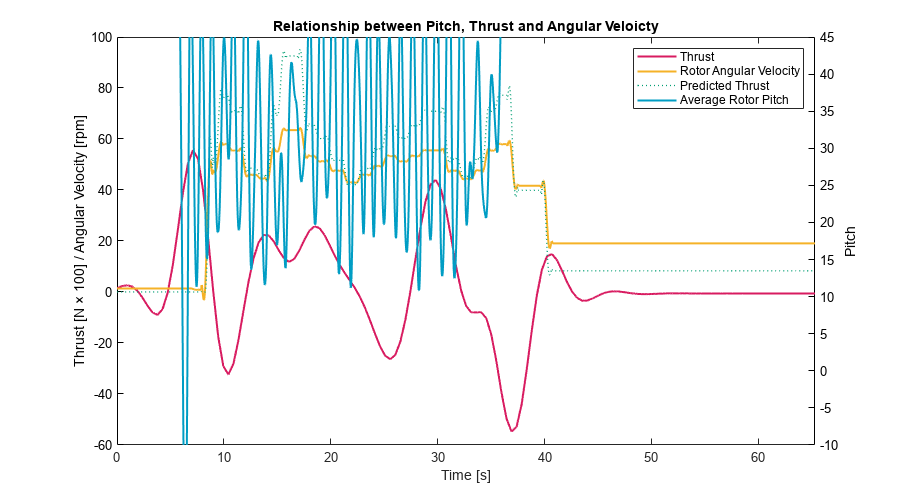

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\TEST 60.1.csv"

resultsBackwardsDirection = 6530×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 14:36:50         60             1.37              30               64                 70               -32            31             -34             32    
    2024-10-15 14:36:50         60             1.37              30               64                 70 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\Pitch Graph-Reverse Flight.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4732    0.9464    1.4196    1.8928    2.3659    2.8391    3.3123    3.7855    4.2587    4.7319    5.2051    5.6783    6.1514    6.6246    7.0978    7.5710    8.0442    8.5174    8.9906    9.4638    9.9370   10.4101   10.8833   11.3565   11.8297   12.3029   12.7761   13.2493   13.7225   14.1957   14.6688   15.1420   15.6152   16.0884   16.5616   17.0348   17.5080   17.9812   18.4543   18.9275   19.4007   19.8739   20.3471   20.8203   21.2935   21.7667   22.2399   22.7130   23.1862


previousItterationPoint = 1

mydata =     0.0151    0.0153    0.0155    0.0156    0.0158    0.0160    0.0162    0.0163    0.0165    0.0167    0.0169    0.0170    0.0172    0.0174    0.0175    0.0177    0.0179    0.0181    0.0182    0.0184    0.0186    0.0188    0.0189    0.0191    0.0193    0.0194    0.0196    0.0198    0.0200    0.0201    0.0203    0.0205    0.0207    0.0208    0.0210    0.0212    0.0213    0.0215    0.0217    0.0219    0.0220    0.0222    0.0224    0.0226    0.0227    0.0229    0.0231    0.0233    0.0234    0.0234


ans = "TEST 60.1"

RMSE = 0.3058

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Forward Direction\TEST 60.1.csv"

resultsBackwardsDirection = 6309×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 11:04:04         60             0.26              10               26                  8               -60             62            -61             45    
    2024-10-15 11:04:04         60             0.26              10               26                  8 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\Pitch Graph-Forward Flight.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4744    0.9487    1.4231    1.8974    2.3718    2.8462    3.3205    3.7949    4.2692    4.7436    5.2180    5.6923    6.1667    6.6411    7.1154    7.5898    8.0641    8.5385    9.0129    9.4872    9.9616   10.4359   10.9103   11.3847   11.8590   12.3334   12.8077   13.2821   13.7565   14.2308   14.7052   15.1795   15.6539   16.1283   16.6026   17.0770   17.5514   18.0257   18.5001   18.9744   19.4488   19.9232   20.3975   20.8719   21.3462   21.8206   22.2950   22.7693   23.2437


previousItterationPoint = 1

mydata =     0.0081    0.0078    0.0075    0.0071    0.0068    0.0065    0.0062    0.0059    0.0056    0.0052    0.0049    0.0046    0.0043    0.0040    0.0036    0.0033    0.0030    0.0027    0.0024    0.0021    0.0017    0.0014    0.0011    0.0008    0.0005    0.0002   -0.0002   -0.0005   -0.0008   -0.0011   -0.0014   -0.0017   -0.0021   -0.0024   -0.0027   -0.0030   -0.0033   -0.0037   -0.0040   -0.0043   -0.0046   -0.0049   -0.0052   -0.0056   -0.0059   -0.0062   -0.0065   -0.0068   -0.0072   -0.0075


ans = "TEST 60.1"

RMSE = 0.2033

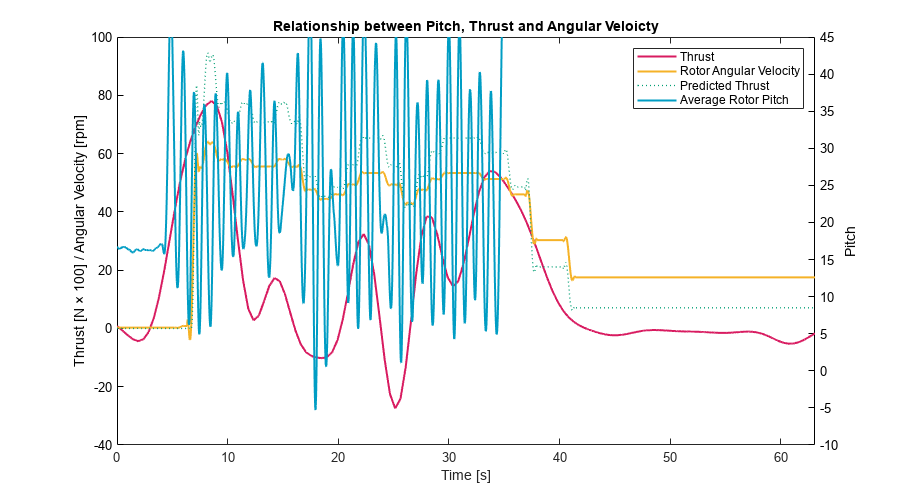

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Speed Sweep\TEST 2.csv"

resultsBackwardsDirection = 9303×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-16 20:43:21         40             4.46              20               25                 43               -59             28            -46             40    
    2024-10-16 20:43:21         40             4.46              20               25                 43 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\Pitch Graph-Speed Sweep.png"

TotalLoadcellScalled =          0    0.0008    0.0016    0.0024    0.0033    0.0041    0.0049    0.0057    0.0065    0.0073    0.0081    0.0089    0.0098    0.0106    0.0114    0.0122    0.0130    0.0138    0.0146    0.0155    0.0163    0.0171    0.0179    0.0187    0.0195    0.0203    0.0211    0.0220    0.0228    0.0236    0.0244    0.0252    0.0260    0.0268    0.0277    0.0285    0.0293    0.0301    0.0309    0.0317    0.0325    0.0333    0.0342    0.0350    0.0358    0.0366    0.0374    0.0382    0.0390    0.0385


ans =          0    0.4820    0.9640    1.4461    1.9281    2.4101    2.8921    3.3741    3.8562    4.3382    4.8202    5.3022    5.7842    6.2663    6.7483    7.2303    7.7123    8.1944    8.6764    9.1584    9.6404   10.1224   10.6045   11.0865   11.5685   12.0505   12.5325   13.0146   13.4966   13.9786   14.4606   14.9426   15.4247   15.9067   16.3887   16.8707   17.3527   17.8348   18.3168   18.7988   19.2808   19.7628   20.2449   20.7269   21.2089   21.6909   22.1730   22.6550   23.1370   23.6190


previousItterationPoint = 1

mydata =     0.0020    0.0010    0.0001   -0.0009   -0.0019   -0.0028   -0.0038   -0.0047   -0.0057   -0.0066   -0.0076   -0.0086   -0.0095   -0.0105   -0.0114   -0.0124   -0.0133   -0.0143   -0.0153   -0.0162   -0.0172   -0.0181   -0.0191   -0.0200   -0.0210   -0.0220   -0.0229   -0.0239   -0.0248   -0.0258   -0.0267   -0.0277   -0.0287   -0.0296   -0.0306   -0.0315   -0.0325   -0.0334   -0.0344   -0.0354   -0.0363   -0.0373   -0.0382   -0.0392   -0.0401   -0.0411   -0.0421   -0.0430   -0.0440   -0.0446


ans = "TEST 2"

RMSE = 0.2430

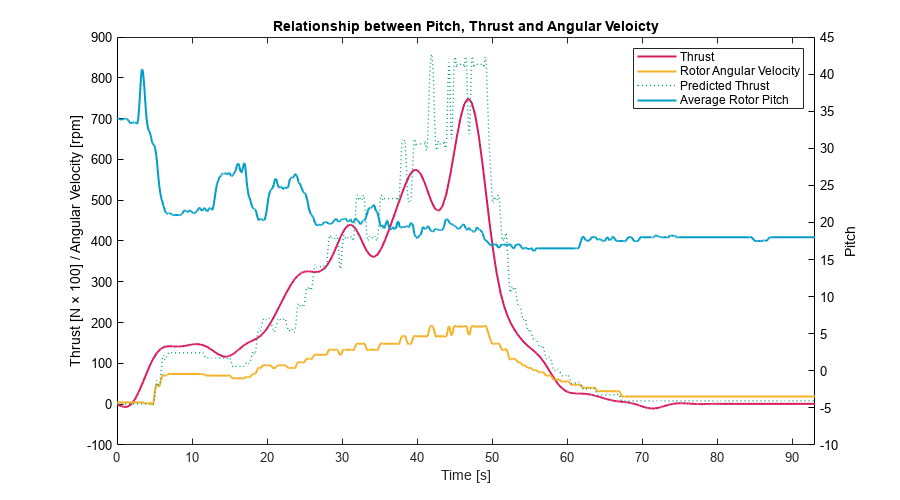

    predictedThrustFunction = @(x) 0.01805 .* (x .* pi/30).^2 + 0.002216 .* (x .* pi/30).^2/0.2625 .*sind(20);
    predictedThrust = predictedThrustFunction(sgolayfilt(resultsBackwardsDirection.("Current Speed"), 4, 111));
    mydata = interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcellsFiltered)), aveargaeLoadcellsFiltered, 1:length(aveargaePitch), 'linear')
    fileName(file)
    RMSE = sqrt(mean(mydata-predictedThrust').^2)
    clear alpha
    yyaxis left
    plot((1:length(aveargaePitch)).*10e-3, interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcellsFiltered)), aveargaeLoadcellsFiltered, 1:length(aveargaePitch), 'linear')*100,'color',"#D81B60", 'DisplayName', 'Thrust', 'LineWidth', 1.5);
    hold on;
    plot((1:length(aveargaePitch)).*10e-3, sgolayfilt(resultsBackwardsDirection.("Current Speed"), 4, 111),'Linestyle','-', 'color',"#f5b227",'DisplayName', 'Rotor Angular Velocity', 'LineWidth', 1.5);
    plot((1:length(aveargaePitch)).*10e-3,predictedThrust*100,'Linestyle',':','color',"#009E73", 'DisplayName', 'Predicted Thrust', 'LineWidth', 1)
    alpha(0); % Set transparency for better visibility
    ylabel('Thrust [N × 100] / Angular Velocity [rpm]');
    ax = gca;
    ax.YColor = 'k'; % Set color to black for consistency

    yyaxis right
    plot((1:length(aveargaePitch))*10e-3, sgolayfilt(aveargaePitch, 4, 111),'color',"#009DC4", 'DisplayName', 'Average Rotor Pitch', 'LineWidth', 1.5);
    alpha(0.2); % Set transparency
    ylabel('Pitch');
    ax.YColor = 'k'; % Set color to black for consistency
    ylim([-10,45])

    xlabel('Time [s]');
    title("Relationship between Pitch, Thrust and Angular Veloicty");

    legend;
    xlim([0,length(resultsBackwardsDirection.Timestamp)*10e-3])
    % grid on;
    hold off;

    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Thrust, Pitch and Speed-" +  imageName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);

end

# PWM

folderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\"

folderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\"

fileName = ["PWM 120"]

fileName = "PWM 120"

imageName = ["PWM 120"]

imageName = "PWM 120"

imageFolderPath ="C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\"

imageFolderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Skripsie Report\Final_Report_LaTeX\Final_Report_LaTeX\figs\Data_Analysis\"

figureWidth = 900; % Width in pixels
figureHeight = 500; % Height in pixels

% Set the figure size
set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

% for file = 1:length(fileName)
file =1

file = 1

    filePath = fullfile(folderPath(file),fileName(file) + ".csv") 

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\PWM 120.csv"

    resultsPWM= readtable(filePath,"VariableNamingRule","preserve")

resultsPWM = 8859×10 table
       Timestamp        Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    10/21/2024 21:49         25              25               20               17                 16               578           -938            904           -775    
    10/21/2024 21:49         25              25               20               17                 16               578          

    previousSpeed = 40;
    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

    aveargaePitch = zeros(1,length(resultsPWM.("Current Pitch 1")));
    for i = 1:length(resultsPWM.("Current Pitch 1"))
        aveargaePitch(i) = (resultsPWM.("Current Pitch 1")(i) + resultsPWM.("Current Pitch 2")(i))/2;
    end
    
     

## Pitch

    % figure;
    % plot((1:length(resultsPWM.Timestamp)).*10e-3, resultsPWM.("Current Pitch 1"),'linewidth',1,'DisplayName','Rotor 1 Pitch','color',"#009DC4")
    % hold on
    % plot((1:length(resultsPWM.Timestamp)).*10e-3, resultsPWM.("Target Pitch"),'r','linewidth',1,'DisplayName','Rotor 1 Target Pitch', 'color',"#f5b227")
    % plot((1:length(resultsPWM.Timestamp)).*10e-3, resultsPWM.("Current Pitch 2"),'linewidth',1,'DisplayName','Rotor 2 Pitch','color',"#D81B60")
    % % plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, aveargaePitch,'linewidth',1,'DisplayName','Average Pitch')
    % ylim([-25,90])
    % xlim([400,length(resultsPWM.("Current Pitch 1"))*2.5/4].*10e-3)
    % hold off
    % ylabel('Pitch [°]');
    % xlabel('Time [s]');
    % title(fullfile("Pitch Variation for " + imageName(file) + " Mode"));
    % legend;
    % 
    % set(gcf, 'Position', [100, 100, 1500, figureHeight]);
    % imageFilePath = fullfile(imageFolderPath,"Pitch Graph-" + imageName(file) + ".png")
    % dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    % print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    % close(gcf);

## Loadcells

    totalTORB_Thrust = ((resultsPWM.("Target Speed")-35)/(60-35)*0.3*9.8 + (resultsPWM.("Current Speed")-35)/(60-35)*0.3*9.8).*2

totalTORB_Thrust =    -4.7040
   -4.7040
   -4.7040
   -4.7040
   -4.7040
   -4.7040
   -4.7040
   -4.7040
   -4.7040
   -4.7040


    for thrust = 1:length(totalTORB_Thrust)
        if totalTORB_Thrust(thrust) < 0
            totalTORB_Thrust(thrust)  = 0;
        end

    end


    resultsPWM.("Load Cell 1") = -(resultsPWM.("Load Cell 1") - resultsPWM.("Load Cell 1")(1)).*0.0098;
    loadcell1 = rmmissing(resultsPWM.("Load Cell 1"));
    loadcell1(isoutlier(resultsPWM.("Load Cell 1"), 'mean')) = NaN;
    loadcell1 = fillmissing(loadcell1, 'linear');
    
    resultsPWM.("Load Cell 2")  = -(resultsPWM.("Load Cell 2")  - resultsPWM.("Load Cell 2") (1)).*0.0098;
    loadcell2 = rmmissing(resultsPWM.("Load Cell 2") );
    loadcell2(isoutlier(resultsFrequencySweep.("Load Cell 2") , 'mean')) = NaN;
    loadcell2 = fillmissing(loadcell2, 'linear');
    
    resultsPWM.("Load Cell 3")  = -((resultsPWM.("Load Cell 3") ) - (resultsPWM.("Load Cell 3") (1))).*0.0098.*0.9;
    loadcell3 = rmmissing(resultsPWM.("Load Cell 3") );
    loadcell3(isoutlier(resultsFrequencySweep.("Load Cell 3") , 'mean')) = NaN;
    loadcell3 = fillmissing(loadcell3, 'linear');
    
    resultsPWM.("Load Cell 4")  = -((resultsPWM.("Load Cell 4") ) - (resultsPWM.("Load Cell 4") (1))).*0.0098.*0.8;
    loadcell4 = rmmissing(resultsPWM.("Load Cell 4") );
    loadcell4(isoutlier(resultsPWM.("Load Cell 4"), 'mean')) = NaN;
    loadcell4 = fillmissing(loadcell4, 'linear');
    
    aveargaeLoadcells = zeros(1,length(loadcell1));
    for i = 1:length(loadcell1)
        aveargaeLoadcells(i) = (loadcell1(i) + loadcell1(i) + loadcell1(i) + loadcell1(i));
    end
    figure;
    plot(linspace(0,length(resultsPWM.Timestamp)*10e-3, length(loadcell1)),loadcell1,'DisplayName','Load Cell 1')
    hold on
    plot(linspace(0,length(resultsPWM.Timestamp)*10e-3, length(loadcell2)),loadcell2,'DisplayName','Load Cell 2')
    plot(linspace(0,length(resultsPWM.Timestamp)*10e-3, length(loadcell3)),loadcell3,'DisplayName','Load Cell 3')
    plot(linspace(0,length(resultsPWM.Timestamp)*10e-3, length(loadcell4)),loadcell4,'DisplayName','Load Cell 4')
    plot(linspace(0,length(resultsPWM.Timestamp)*10e-3, length(aveargaeLoadcells)),aveargaeLoadcells,'r','linewidth',1, 'DisplayName','Combined Load Cells')

    xlim([0,length(resultsPWM.Timestamp)*10e-3])
    hold off
    ylabel('Thrust [N]');
    xlabel('Time [s]');
    title(fullfile("Unfiltered Loadcell Output for " + imageName(file) + " Mode"));
    legend;
    TotalLoadcellScalled = interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcells)), aveargaeLoadcells, 1:length(aveargaePitch), 'linear')

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


    linspace(0,length(resultsPWM.Timestamp)*10e-3, length(loadcell2))

ans =          0    0.4841    0.9682    1.4523    1.9364    2.4205    2.9046    3.3887    3.8728    4.3569    4.8410    5.3251    5.8092    6.2933    6.7774    7.2615    7.7456    8.2297    8.7138    9.1979    9.6820   10.1661   10.6502   11.1343   11.6184   12.1025   12.5866   13.0707   13.5548   14.0389   14.5230   15.0070   15.4911   15.9752   16.4593   16.9434   17.4275   17.9116   18.3957   18.8798   19.3639   19.8480   20.3321   20.8162   21.3003   21.7844   22.2685   22.7526   23.2367   23.7208


    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

    % imageFilePath = fullfile(imageFolderPath,"Unfiltered Loadcell Readings-" +  imageName(file)+ ".png");
    % dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    % print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    % close(gcf);
    % plot(linspace(0,length(resultsPWM.Timestamp)*10e-3, length(loadcell1)),loadcell1)
    period = 0.44;
    fs = 1/period;   % Sampling Frequency
    nyquist_freq = fs/2 ;
    previousItterationPoint = 1

previousItterationPoint = 1

## Filtered

    
    
    cutOffFrequency = 0.2;
    nOrder = 4;
    
    [b,a] = butter(nOrder,cutOffFrequency/(fs/2));
    loadcell1Filtered = filtfilt(b,a,loadcell1);
    loadcell2Filtered = filtfilt(b,a,loadcell2);
    loadcell3Filtered = filtfilt(b,a,loadcell3);
    loadcell4Filtered = filtfilt(b,a,loadcell4);
    
    aveargaeLoadcellsFiltered = zeros(1,length(loadcell1Filtered));
    % deltaThrust = (loadcell4Filtered+loadcell1Filtered) - (loadcell3Filtered+loadcell2Filtered);

    for i = 1:length(loadcell1Filtered)
        aveargaeLoadcellsFiltered(i) = (loadcell1Filtered(i) + loadcell2Filtered(i) + loadcell3Filtered(i) + loadcell4Filtered(i));
    end
    figure;
    plot(linspace(0,length(resultsPWM.Timestamp)*10e-3, length(loadcell1Filtered)),loadcell1Filtered,'DisplayName','Load Cell 1')
    hold on
    plot(linspace(0,length(resultsPWM.Timestamp)*10e-3, length(loadcell2Filtered)),loadcell2Filtered,'DisplayName','Load Cell 2')
    plot(linspace(0,length(resultsPWM.Timestamp)*10e-3, length(loadcell3Filtered)),loadcell3Filtered,'DisplayName','Load Cell 3')
    plot(linspace(0,length(resultsPWM.Timestamp)*10e-3, length(loadcell4Filtered)),loadcell4Filtered,'DisplayName','Load Cell 4')
    plot(linspace(0,length(resultsPWM.Timestamp)*10e-3, length(aveargaeLoadcellsFiltered)),aveargaeLoadcellsFiltered,'r','linewidth',1, 'DisplayName','Combined Thrust')
    yline(mean(aveargaeLoadcellsFiltered(aveargaeLoadcellsFiltered > 1.3.*mean(aveargaeLoadcellsFiltered))),'--b','DisplayName','Average Thrust')
        plot(linspace(0,length(resultsPWM.Timestamp)*10e-3, length(totalTORB_Thrust)),totalTORB_Thrust,"-.",'linewidth',1, 'DisplayName','TORB Thrust','color',"#009E73")
    hold off
    xlim([0,length(resultsPWM.Timestamp)*10e-3])
    ylabel('Thrust [N]');
    xlabel('Time [s]');
    title("Input TORB Thrust vs Output Thrust");
    legend;
    
    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Thrust Generated-" +  imageName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);

           mean(aveargaeLoadcellsFiltered(aveargaeLoadcellsFiltered > 1.3.*mean(aveargaeLoadcellsFiltered)))

ans = 4.2015

           mean(totalTORB_Thrust(totalTORB_Thrust > 1.3.*mean(totalTORB_Thrust)))

ans = 2.2041


           mean(aveargaeLoadcellsFiltered(aveargaeLoadcellsFiltered > 1.3.*mean(aveargaeLoadcellsFiltered))) - mean(totalTORB_Thrust(totalTORB_Thrust > 1.3.*mean(totalTORB_Thrust)))*sind(20)

ans = 3.4477


       mean(aveargaeLoadcellsFiltered(aveargaeLoadcellsFiltered > 1.3.*mean(aveargaeLoadcellsFiltered)))/ mean(totalTORB_Thrust(totalTORB_Thrust > 1.3.*mean(totalTORB_Thrust)))*100

ans = 190.6254

## Combined

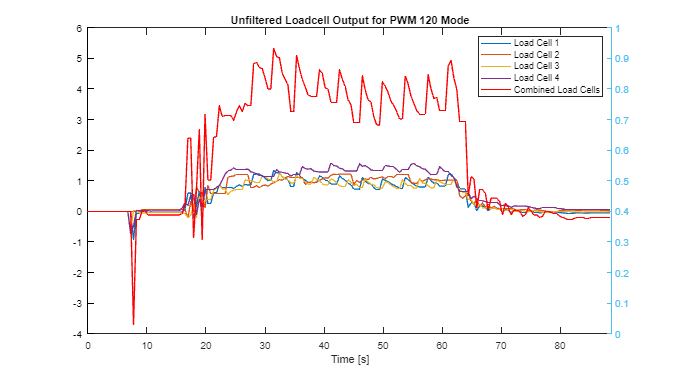

    predictedThrustFunction = @(x) 0.01805 .* (x .* pi/30).^2 + 0.002216 .* (x .* pi/30).^2/0.2625 .*sind(20);
    predictedThrust = predictedThrustFunction(sgolayfilt(resultsPWM.("Current Speed"), 4, 111));
    
    clear alpha
    yyaxis left
    plot((1:length(aveargaePitch)).*10e-3, interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcellsFiltered)), aveargaeLoadcellsFiltered, 1:length(aveargaePitch), 'linear')*100,'color',"#D81B60", 'DisplayName', 'Thrust', 'LineWidth', 1.5);

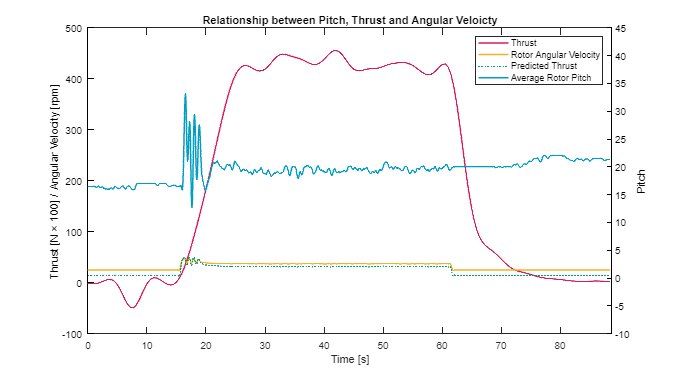

    hold on;
    plot((1:length(aveargaePitch)).*10e-3, sgolayfilt(resultsPWM.("Current Speed"), 4, 111),'Linestyle','-', 'color',"#f5b227",'DisplayName', 'Rotor Angular Velocity', 'LineWidth', 1.5);
    plot((1:length(aveargaePitch)).*10e-3,predictedThrust*100,'Linestyle',':','color',"#009E73", 'DisplayName', 'Predicted Thrust', 'LineWidth', 1)
    alpha(0); % Set transparency for better visibility
    ylabel('Thrust [N × 100] / Angular Velocity [rpm]');
    ax = gca;
    ax.YColor = 'k'; % Set color to black for consistency
    
    yyaxis right
    plot((1:length(aveargaePitch))*10e-3, sgolayfilt(aveargaePitch, 4, 111),'color',"#009DC4", 'DisplayName', 'Average Rotor Pitch', 'LineWidth', 1.5);
    alpha(0.2); % Set transparency
    ylabel('Pitch');
    ax.YColor = 'k'; % Set color to black for consistency
    ylim([-10,45])
        
    xlabel('Time [s]');
    title("Relationship between Pitch, Thrust and Angular Veloicty");

    legend;
    xlim([0,length(resultsPWM.Timestamp)*10e-3])
    % grid on;
    hold off;

    % 
    % set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
    % imageFilePath = fullfile(imageFolderPath,"Thrust, Pitch and Speed-" +  imageName(file) + ".png");
    % dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    % print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    % close(gcf);

% end